Select source data folder. Data folder shold have the following structure:

src_data

----damaged

----healthy

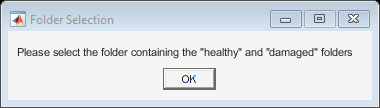

[fileStruct, folderPath] = selectFolderAndListFiles();

fileStruct: struct with the filenames of each folder ("healthy" and "damaged").

folderPath: absolute path of where folders "healthy" and "damaged" are located.

%%%%%%%%%%%

If "`Error using processTDMSFiles Specified TDMS file might be unsupported v1.0`"

Use the the live script **tscm.data_conversion.mlx**

%%%%%%%%%%%

fileList_healthy = fileStruct.healthy;
fileList_damaged = fileStruct.damaged;

The struct has been divided in two lists, which are going to be converted into a struct of tables containing all files

decimateFactor = 500;

tdmsTables_healthy = processTDMSFiles(fileList_healthy, folderPath, decimateFactor);
tdmsTables_damaged = processTDMSFiles(fileList_damaged, folderPath, decimateFactor);

tableFeatures_healthy = extractTableFeatures(tdmsTables_healthy);
tableFeatures_damaged = extractTableFeatures(tdmsTables_damaged);

exportTableToCSV(tableFeatures_healthy);
exportTableToCSV(tableFeatures_damaged);